 vid=VideoReader('test.mp4');
 numFrames = vid.NumberOfFrames;
 n=numFrames;
 for i = 1:2:n
 frames = read(vid,i);
 %imwrite(frames,['Image' int2str(i), '.jpg']);
 im(i)=image(frames);
 end

Expected index to be positive.

di = compute_approximate_dynamic_images(frames)

di = 576×720×3 single array
di(:,:,1) =

    68    68    68    68    68    68    68    68    67    67    68    68    68    68    71    84     0     6    16    19    22    36    67    72    72    74    76    76    76    77    82    84    88    91    92    97    98   100   104   107   110   111   113   115   117   120   125   127   129   130   132   133   135   136   138   139   139   140   141   143   144   145   147   148   150   152   153   154   157   158   159   161   162   162   164   164   165   166   166   166   167   167   167   168   168   169   169   169   169   171   171   171   172   172   173   173   173   173   174   174   175   175   175   176   176   176   178   178   179   178   178   178   176   178   179   179   179   179   180   180   180   180   181   181   181   181   181   181   180   181   181   181   182   182   182   182   182   182   182   182   182   182   182   182   183   183   183   183   183   183   183   183   185   185   185   185   185   185   185   18

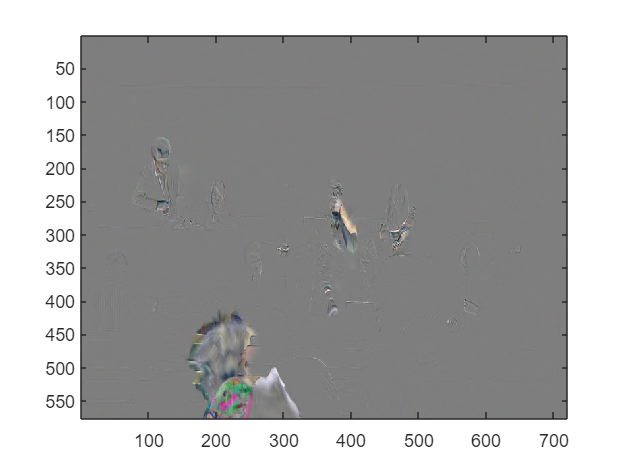

%list = read(vid,1);
visualize_approximate_dynamic_images(list)

list(:,:,:,4)

ans = 576×720×3 uint8 array
ans(:,:,1) =

    58    58    58    58    58    58    58    58    57    57    57    57    56    56    58    76     0     0     8     9    12    25    61    68    70    72    73    73    74    78    83    84    87    89    94    95    97   100   103   105   108   109   111   114   116   117   119   121   122   125   126   127   128   128   128   129   131   133   134   136   136   139   140   141   142   143   146   147   148   149   152   154   154   155   155   155   156   156   157   157   157   159   159   160   160   160   161   161   162   162   163   163   163   164   164   164   164   165   165   165   167   167   167   167   168   168   168   168   168   168   169   170   171   172   172   172   172   172   172   172   172   172   173   173   174   174   174   174   175   175   175   175   175   175   175   175   176   176   176   176   176   176   176   176   176   176   176   176   176   176   176   176   178   178   178   178   178   178   178   1

list = cat(4,read(vid,1),read(vid,2),read(vid,3),read(vid,4), read(vid,5),read(vid,6))

list = 576×720×3×6 uint8 array
list(:,:,1,1) =

    58    58    58    58    58    58    58    58    57    57    57    57    56    56    58    77     0     1    10    10    14    27    63    68    70    71    73    73    74    77    82    84    87    89    94    95    97   100   103   105   108   109   111   114   116   117   119   121   122   125   126   127   128   128   128   129   129   132   134   136   136   139   141   142   143   145   147   148   149   150   153   154   155   155   155   155   156   156   157   157   157   159   159   160   160   160   161   161   162   162   163   163   163   164   164   164   164   165   165   165   167   167   167   167   168   168   168   168   168   168   169   170   171   172   172   172   172   172   172   172   172   172   173   173   174   174   174   174   175   175   175   175   175   175   175   175   176   176   176   176   176   176   176   176   176   176   176   176   176   176   176   176   176   176   176   176   176   176   1

for i = 1:10:n
    frames1 = read(vid,i);
    frames2 = read(vid,i+1);
    frames3 = read(vid,i+2);
    frames4 = read(vid,i+3);
    frames5 = read(vid,i+4);
    frames6 = read(vid,i+5);
    frames7 = read(vid,i+6);
    frames8 = read(vid,i+7);
    frames9 = read(vid,i+8);
    frames10 = read(vid,i+9);
    list = cat(4,frames1,frames2, frames3,frames4,frames5,frames6,frames7,frames8,frames9,frames10);
    %visualize_approximate_dynamic_images(list)
    di = compute_approximate_dynamic_images(list);
    di = di - min(di(:)) ;
    di = 255 * di ./ max(di(:)) ;
    imwrite(uint8(di),['DI' int2str(i-1), '.jpg']);
end

i = 0

i = 10

i = 20

i = 30

i = 40

i = 50

i = 60

i = 70

i = 80

i = 90

i = 100